## Load processed ephys data (with odor and movement epoch tables)

parentDir = 'D:\Dropbox (HMS)\Ephys data';
expDirs = dir(fullfile(parentDir, '2017*'));

load(fullfile(parentDir, 'LHDAN_ephys_data.mat'), 'LHDAN_ephys_data');
expData = LHDAN_ephys_data;

load(fullfile(parentDir, ['odorStimTable_pre_4_post_5.mat']), 'odorStimTable');
load(fullfile(parentDir, ['moveEpochTable_minDur_0.2_quiescenceWin_1_analysisDur_2.mat']), ...
    'moveEpochTable');

## Restrict analysis to cell types of interest

currCellTypes = {'B', 'D', 'PPM2'};

moveEpochTable = moveEpochTable(ismember(moveEpochTable.cellType, currCellTypes), :);
odorStimTable = odorStimTable(ismember(odorStimTable.cellType, currCellTypes), :);


## Plot voltage traces and rasters for each experiment

Set up plotting parameters

p = [];
p.smWin = 1000;
p.medFilt = 1;
p.medFiltWin = 600;
p.singleTrials = 0;
p.baselineOffset = 0;

p.maxOdors = 4;
p.expPerFigure = 4;
p.figDims = [1200 800];


Create data table

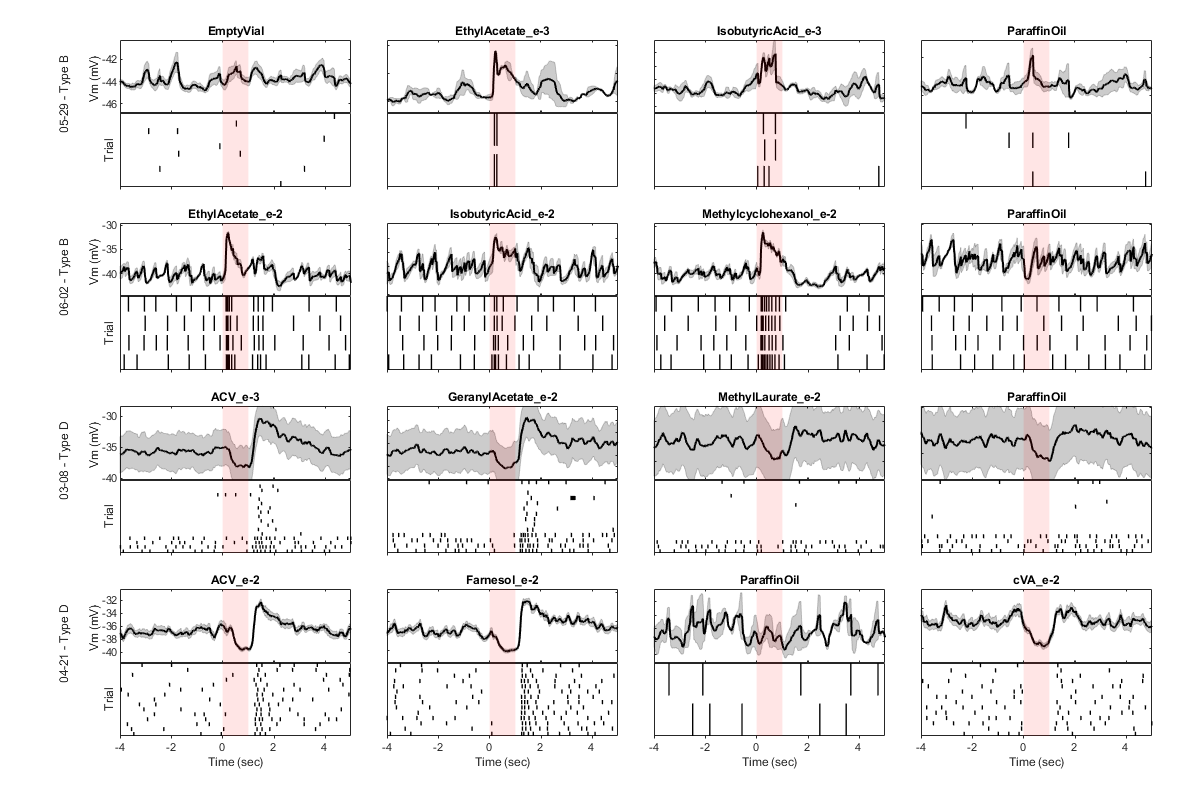

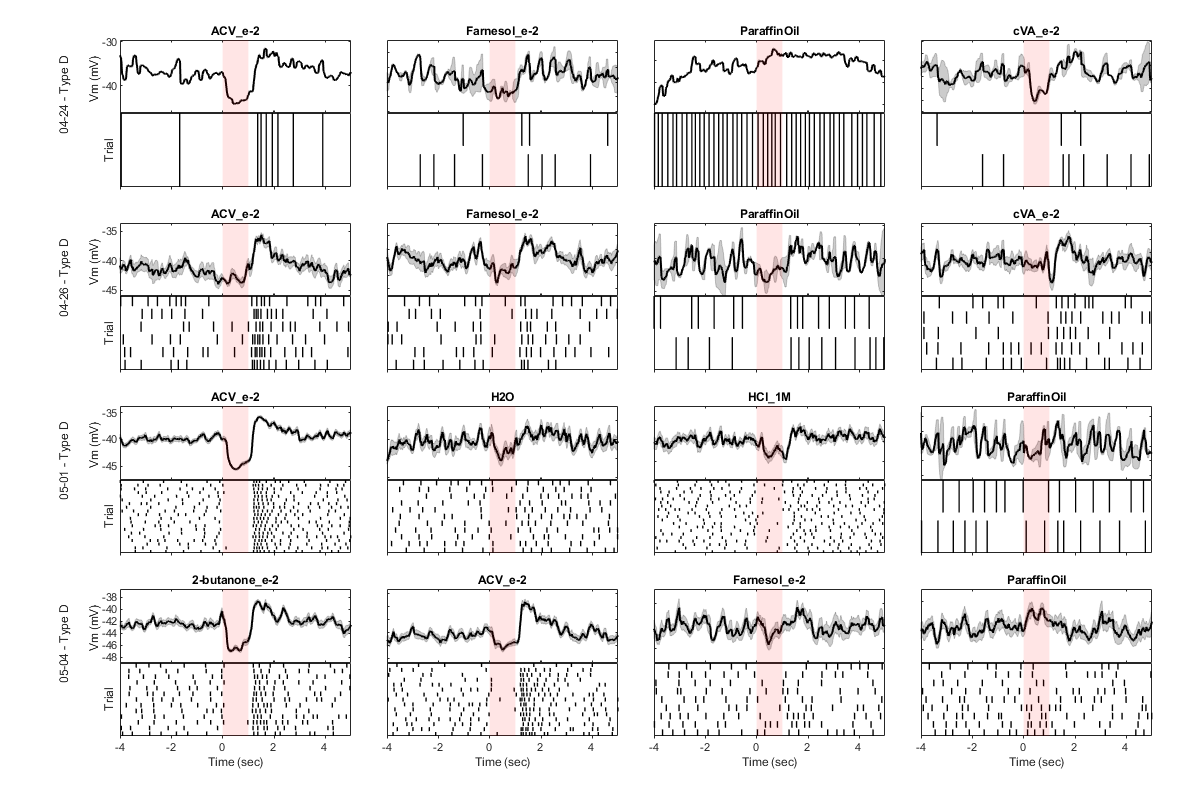

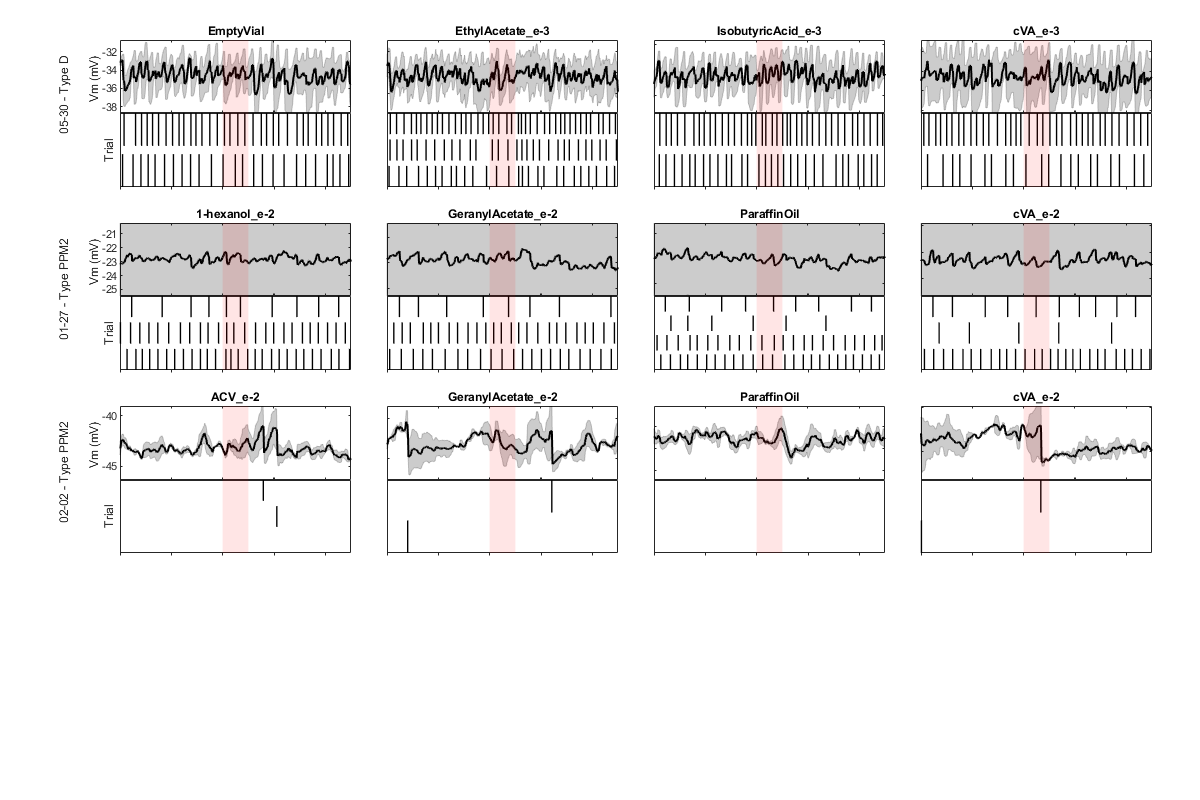

dt = DataTable(sortrows(odorStimTable, {'cellType', 'expID'}));

filterDefs = [];
filterDefs.excludeMove = 1;
dt = dt.initialize_filters(filterDefs);
uniqueExps = unique(dt.subset.expID, 'stable');


figs = {};
figs{1} = figure(1); clf;
figs{1}.Color = [1 1 1];
if ~isempty(p.figDims)
    figs{1}.Position(3:4) = p.figDims;
end

expCount = 1; figCount = 1;
for iExp = 1:size(uniqueExps, 1)
    
   % Create a new figure if necessary
   if expCount > p.expPerFigure
       
       % Create new figure
       figs{figCount}.UserData.plotParams = p;
       figCount = figCount + 1;
       expCount = 1;
       figs{figCount} = figure(figCount);clf
       figs{figCount}.Color = [1 1 1];
       if ~isempty(p.figDims)
           figs{figCount}.Position(3:4) = p.figDims;
       end
   end
    
   % Get data for just the current experiment
   filterDefs.expID = uniqueExps{iExp};
   filterDefs.odor = [];
   dt = dt.initialize_filters(filterDefs);
   
   % Plot data for each odor
   odorList = unique(dt.subset.odor);
   for iOdor = 1:numel(odorList)
       if iOdor > p.maxOdors; continue; end % Temporary
       
       % Get data for just this odor
       filterDefs.odor = odorList{iOdor};
       dt = dt.initialize_filters(filterDefs);
       
       
       % Create axes for voltage plot
       axCountY = (5*p.expPerFigure) - 1;
       currAxOffsetY = 5 * (expCount - 1);
       ax = subaxis(axCountY, p.maxOdors, iOdor, currAxOffsetY + 1, 1, 2, ...
                'mr', 0.04, 'ml', 0.1, 'mb', 0.08, 'mt', 0.05, 'sh', 0.03, 'sv', 0);
       
       % Get (downsampled) voltage data 
       voltage = smoothdata(cell2mat(dt.subset.voltage'), 1, 'gaussian', p.smWin, 'omitnan');
       voltage = voltage(1:5:end, :);
       
       % Median filter to reduce spike size if desired
       if p.medFilt
           voltage = movmedian(voltage, p.medFiltWin, 1, 'omitnan');
       end
       
       % Offset voltage to have the same baseline if desired
       if p.baselineOffset
           voltage = voltage - repmat(median(voltage, 1, 'omitnan'), size(voltage, 1), 1);
       end
       
       % Calculate plotting times
       sampTimes = (1:size(voltage, 1)) ./ (dt.subset.sampRate(1) / 5);
       odorOnsetTime = dt.subset.analysisWinSec{1}(1);
       odorOffsetTime = dt.subset.stimDur(1);
       plotTimes = sampTimes - odorOnsetTime;
        
       % Plot single trial data if desired, otherwise shade +/- SEM
       if p.singleTrials
           plot(plotTimes, voltage, 'linewidth', 0.5);
       else
           % Shade +/- SEM downsampled even further)
           dsVoltage = voltage(1:100:end, :);
           dsPlotTimes = plotTimes(1:100:end);
           sd = std(dsVoltage, [], 2, 'omitnan');
           avg = mean(dsVoltage, 2, 'omitnan');
           sd = sd(~isnan(dsPlotTimes));
           avg = avg(~isnan(dsPlotTimes));
           sem = sd ./ (size(dsVoltage, 2)^0.5);
           jbfill(dsPlotTimes(~isnan(dsPlotTimes)), [avg + sem]', [avg - sem]', 'k', 'k', 1, 0.2);
       end
       
       % Plot mean voltage
       hold on
       plot(plotTimes, mean(voltage, 2), 'linewidth', 1.5, 'color', 'k')
       
       % Shade stim epoch
       plot_stim_shading([0 odorOffsetTime])
       
       % Adjust plot axes
       title(regexprep(odorList{iOdor}, '_', '\\_'), 'fontsize', 11)
       if p.singleTrials
           ylim([min(voltage(:), [], 'omitnan') - 2, max(voltage(:), [], 'omitnan') + 2])
       else
           ylim([min(mean(voltage, 2, 'omitnan'), [], 'omitnan') - 2, ...
                    max(mean(voltage, 2, 'omitnan'), [], 'omitnan') + 2]);
       end
       xlim([plotTimes(1), plotTimes(end)])
       ax = gca;
       if expCount == p.expPerFigure
           xlabel('Time (sec)')
           xL = xlim();
       else
           xlabel('')
           ax.XTickLabel = '';
       end
       if iOdor == 1
           yL = ylim;
          if p.baselineOffset
              unitStr = '\Delta Vm (mV)';
              shiftDist = 0.4 * diff(yL);
          else
              unitStr = 'Vm (mV)';
              shiftDist = 0.3 * diff(yL);
          end
          t = ylabel({[uniqueExps{iExp}(5:6), '-', uniqueExps{iExp}(7:8), ...
              ' - Type ', dt.subset.cellType{1}], '', unitStr}, 'fontsize', 11, ...
              'horizontalalignment', 'right');
          t.Position(2) = t.Position(2) + shiftDist;
       else
           ax.YTickLabel = [];
       end           
       
       % Create axes for spike rasters
       ax = subaxis(axCountY, p.maxOdors, iOdor, currAxOffsetY + 3, 1, 2, ...
            'mr', 0.04, 'ml', 0.1, 'mb', 0.08, 'mt', 0.05, 'sh', 0.03, 'sv', 0);
       
       % Get spike times for current trials
       spikeTimes = [];
       nTrials = size(dt.subset, 1);
       trialLenSamples = size(dt.subset.voltage{1}, 1);
       sampRate = dt.subset.sampRate(1);
       for iTrial = 1:nTrials
           spikeTimes = [spikeTimes; dt.subset.spikeSamples{iTrial} + ...
                (trialLenSamples * (iTrial - 1))];
       end
       
       % Calculate plotting times
       odorOnsetTime = dt.subset.analysisWinSec{1}(1);
       odorOffsetTime = odorOnsetTime + dt.subset.stimDur(1);
       
       % Plot raster
       rasterplot(spikeTimes, nTrials, trialLenSamples, 'plotAxes', ax, 'sampRate', sampRate);
       
       % Shade stim epoch
       hold on
       plot_stim_shading([odorOnsetTime odorOffsetTime])
       
       % Adjust plot axes
       ax = gca;
       ax.XLim(1) = 0;
       if expCount == p.expPerFigure
           xlabel('Time (sec)')
           xL = xlim();
           ax.XTickLabel = {cellfun(@str2double, ax.XTickLabel) - odorOnsetTime};
       else
           xlabel('')
           ax.XTickLabel = '';
       end
       if iOdor == 1
           ylabel('Trial')
       else
           ylabel('')
       end

   end%iOdor
   
   expCount = expCount + 1;
   
end%iExp

## Save final figures

saveDir = 'D:\Dropbox (HMS)\Ephys data\LHDAN_Summary_Analyses';
for iFig = 1:numel(figs)
    saveName = ['odor_responses_meanTraces+rasters_part_', num2str(iFig)];
    save_figure(figs{iFig}, saveDir, saveName);
end